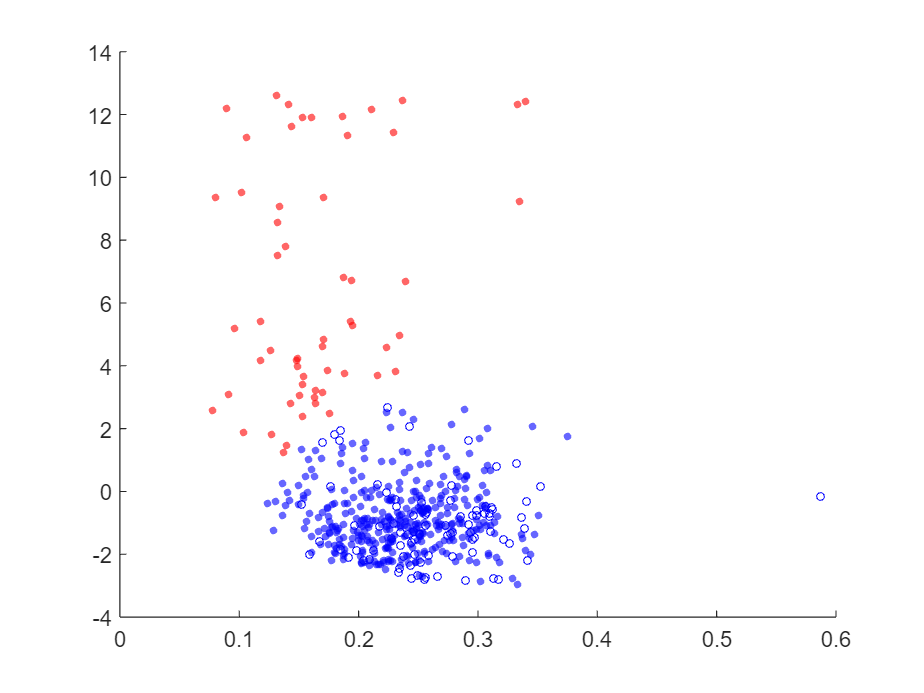

clusterBy = 'PC';
% if nargin < 2
%     if isfield(r, 'ChanMap')
        spatial = r.ChanMap;
%     else
%         error('Lack spatial information');
%     end
% end

% number of spikes (units)
nSpk = size(r.Units.SpikeNotes, 1);

% channel location [x, y]
channel_locations = [spatial.xcoords, spatial.ycoords];

% Set parameters and initialize outputs
Fs = 30000; % sample rate (Hz)

% kilosort groups
good = r.Units.SpikeNotes(:,3)==1;

% for autocorrelation
binSize = 1; % (ms)
maxLag = 50; % (ms)
autoCorr = []; % compute auto correlogram
tCorr    = [];

% for waveform plotting
nWave = 5; % collect the waveform from the first 5 channels with the largest spike size
waveCollection = cell(1, nWave);
amplitudes = zeros(2, nSpk); % spike size in the first 2 channels

% spike features
peakTrough          = zeros(1, nSpk); % abs(Peak / Trough)
tPeakTrough         = zeros(1, nSpk); % interval between peak and trough
fullWidthHalfHeight = zeros(1, nSpk);

% unit location in 3D space
nNearest = 40;
unitLocation.where = zeros(3, nSpk);
unitLocation.what  = zeros(1, nSpk); % size of the spike (this differs from the max size in a channel)
unitLocation.type  = good; % type of the spike (from kilosort)

% Calculate spike features and locations for each unit
for i = 1:nSpk
    allWaves = r.Units.SpikeTimes(i).wave_mean; % n_channels * n_samples
    nSample  = size(allWaves, 2);
    twave    = (1:nSample)*1000/Fs; % in ms
    
    % find out the largest waveform
    spikeSize = abs(max(allWaves, [], 2)-min(allWaves, [], 2)); % this is a nCh x 1 vector.
    [spikeSizeSorted, indSort] = sort(spikeSize, 'descend');
    amplitudes(1, i) = spikeSizeSorted(1);
    amplitudes(2, i) = spikeSizeSorted(2);

    % get spike features
    feature_out = spike_features(twave, allWaves(indSort(1), :));
    peakTrough(i)  = feature_out.peak2trough;
    tPeakTrough(i) = feature_out.t_peak2trough;
    fullWidthHalfHeight(i) = feature_out.fwhh;

    % collect the first 5 channels
    for j = 1:nWave
        wave_this = allWaves(indSort(j), :);
        if -min(wave_this)<max(wave_this) % regular spike, negative phase is larger than the  positive phase
            wave_this = -wave_this;
        end
        waveCollection{j} = [waveCollection{j}; wave_this];
    end
% 
%     % get autocorrelation
%     spikeTimes = r.Units.SpikeTimes(i).timings;
%     [lags, counts] = computeACG(spikeTimes, binSize, maxLag);
%     if isempty(tCorr)
%         tCorr = lags;
%     end
%     autoCorr = [autoCorr; counts'];
% 
%     % based on allWaves, compute the location of the unit.
%     % use this function from Yue Huang
%     % function [x, y, z, ptt] = spikeLocation(waveforms_mean, channel_locations, n_nearest_channels, algorithm)
%     [unitLocation.where(1, i), unitLocation.where(2, i), unitLocation.where(3, i)] = spikeLocation(allWaves, channel_locations, nNearest, 'monopolar_triangulation');
%     unitLocation.what(i) = spikeSizeSorted(1);
% 
end
% 
% % Save unit location
% unit_location_name = sprintf('unitLocation_%s_%s.mat', r.BehaviorClass.Subject, r.BehaviorClass.Session);
% save(unit_location_name, 'unitLocation')

% Cluster analysis
switch clusterBy
    case 'PeakTrough'
        X1 = peakTrough(:);
    case 'PC'
        wave_z = zscore(waveCollection{1}, [], 2);
        [~, PC] = pca(wave_z);
        X1 = PC(:,1);
end
X = [X1, fullWidthHalfHeight(:)];
% Normalize data (optional, if scales differ)
X = (X - mean(X)) ./ std(X);
% Run kmeans with optimized parameters
[cidx, ctrs] = kmeans(X, 2, ...
    'Distance', 'sqeuclidean', ...
    'Replicates', 5, ...
    'Start', 'plus', ...
    'EmptyAction', 'singleton', ...
    'MaxIter', 200, ...
    'Display', 'off');

% % Re-assign cluster index by counts
% count1 = sum(cidx==1); % Number of points in cluster 1
% count2 = sum(cidx==2); % Number of points in cluster 2
% % swap indices if cluster 2 is larger
% if count2 > count1
%     cidx = 3 - cidx; % Converts 1 to 2 and 2 to 1
%     ctrs = ctrs([2 1], :); % Swap centroid rows to match
% end

% Re-assign cluster index by fwhh
if ctrs(2,2) > ctrs(1,2)
    cidx = 3 - cidx; % Converts 1 to 2 and 2 to 1
    ctrs = ctrs([2 1], :); % Swap centroid rows to match
end

%
GoodRegularIndex = find(good & cidx==1);
% disp(GoodRegularIndex)
MUARegularIndex = find(~good & cidx==1);
% disp(MUARegularIndex)
IRRegularIndex = find(cidx==2);

RegularIndex.Good = GoodRegularIndex;
RegularIndex.MUA = MUARegularIndex;

RegularIndex.Ind = zeros(nSpk,1);
RegularIndex.Ind(GoodRegularIndex) = 1;
RegularIndex.Ind(MUARegularIndex)  = 2;
RegularIndex.Ind(IRRegularIndex)   = 0;

figure(); hold on;
scatter(fullWidthHalfHeight(cidx==1 & good), X1(cidx==1 & good), 12, 'blue', 'filled', 'MarkerFaceAlpha', .6);
scatter(fullWidthHalfHeight(cidx==1 & ~good), X1(cidx==1 & ~good),  12, 'blue');
scatter(fullWidthHalfHeight(cidx==2), X1(cidx==2),  12, 'red','filled', 'MarkerFaceAlpha', .6);

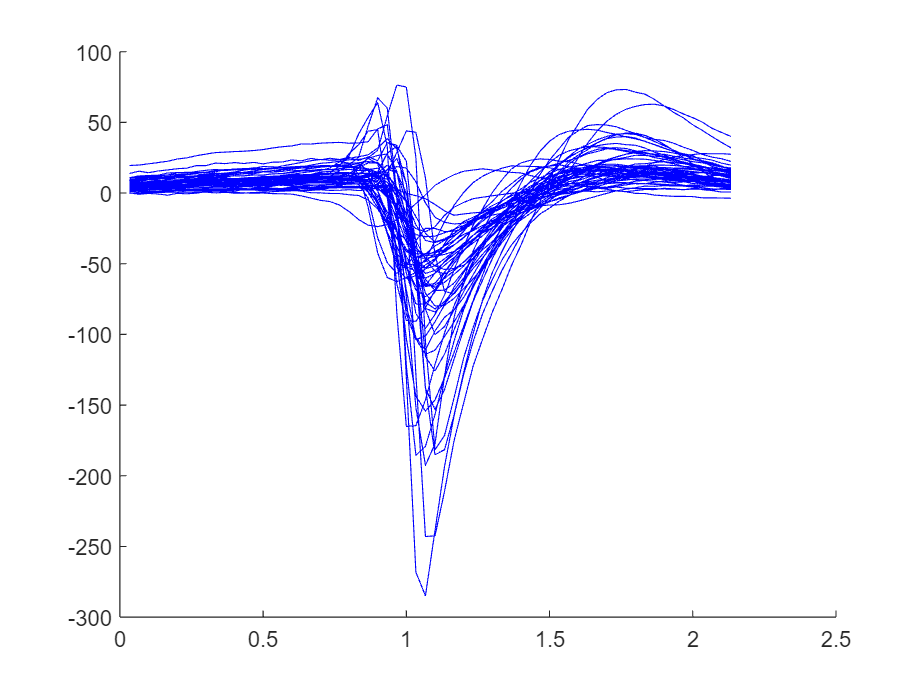


figure(); hold on;
wave_regular = waveCollection{j}(cidx==1 & good, :);
n_regular = sum(cidx==1 & good);
if n_regular > 50
    wave_regular = wave_regular(randperm(n_regular, 50), :);
end
for i = 1:size(wave_regular, 1)
    plot(twave, wave_regular(i,:), 'b');
end

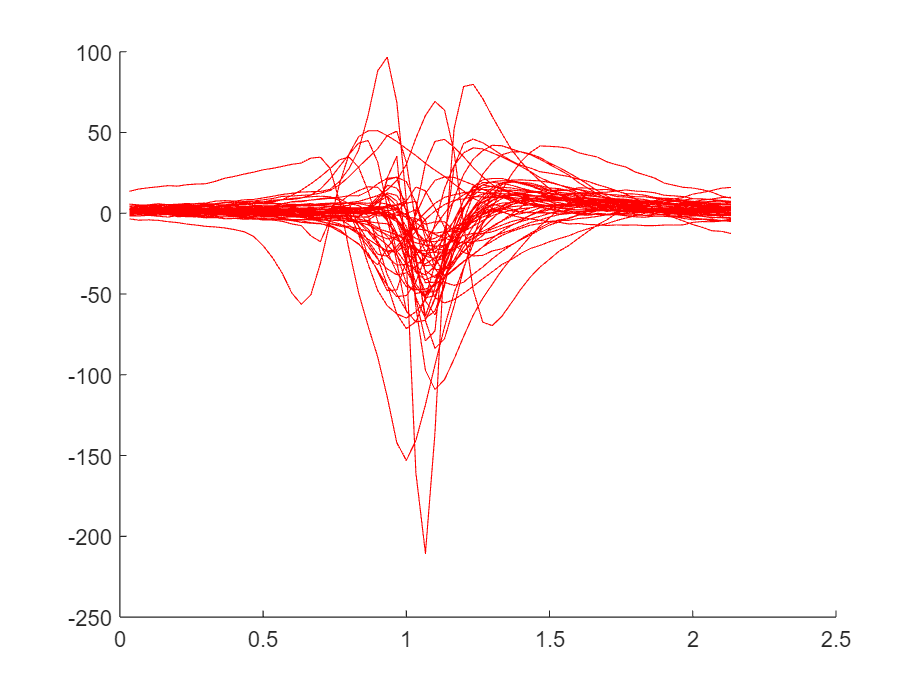


figure(); hold on;
wave_irregular = waveCollection{j}(cidx==2, :);
n_irregular = sum(cidx==2);
if n_irregular > 50
    wave_irregular = wave_irregular(randperm(n_irregular, 50), :);
end
for i = 1:size(wave_irregular, 1)
    plot(twave, wave_irregular(i,:), 'r');
end